# Computational Methods in Physics (PHY4605) - **Numerical Differential Equations**

## Overview

The most interesting situations in real life that we may want to model, or represent quantitatively, are usually those in which the variables change in time (e.g., biological, electrical or mechanical systems). If the changes are continuous, the system can often be represented with equations involving the derivatives of the dependent variables. Such equations are called differential equations. The main aim of a lot of modeling is to be able to write down a set of differential equations (DEs) that describe the system being studied as accurately as possible. Very few DEs can be solved analytically, so once again, numerical methods are required.

## Euler’s Method

In general we want to solve a first-order DE (strictly an ordinary—ODE) of the form $\textrm{dy}/\textrm{dx}=f\left(x,y\right),$ $y\left(0\right)$ given. Euler’s method for solving this DE numerically consists of replacing $\textrm{dy}/\textrm{dx}$ with its Newton quotient, so that the DE becomes:

 
$$\frac{y\left(x+h\right)-y\left(x\right)}{h}=f\left(x,y\right)$$


After a slight rearrangement of terms, we get:


$$y\left(x+h\right)=y\left(x\right)+\textrm{hf}\left(x,y\right)$$


In the equation, $h$ is the width of subintervals, obtained by dividing the full interval of integration from $x=a$ (where usually $a=0$) to $x=b$ into $n$ subintervals, i.e., $h=\frac{b-a}{n}$.

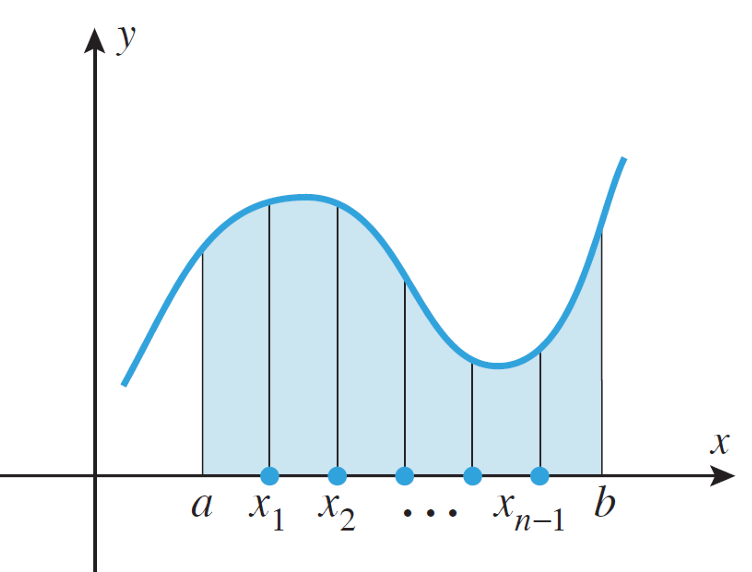

Suppose we start at the beginning, where $x_0 =0$, and $y_0 =y\left(0\right)$ is given. We can then estimate that at the next point of $x$ where $x_1 =\textrm{ih}=\left(1\right)h$, $y_1 =y_0 +\textrm{hf}\left(x_0 ,y_0 \right)$. We can continue doing the same thing for subsequent $i$'s: $i=2,3,4,\ldotp \ldotp \ldotp ,n$ by using the general formula:


$$y_{i+1} =y_i +\textrm{hf}\left(x_{i,} {\;y}_i \right)$$


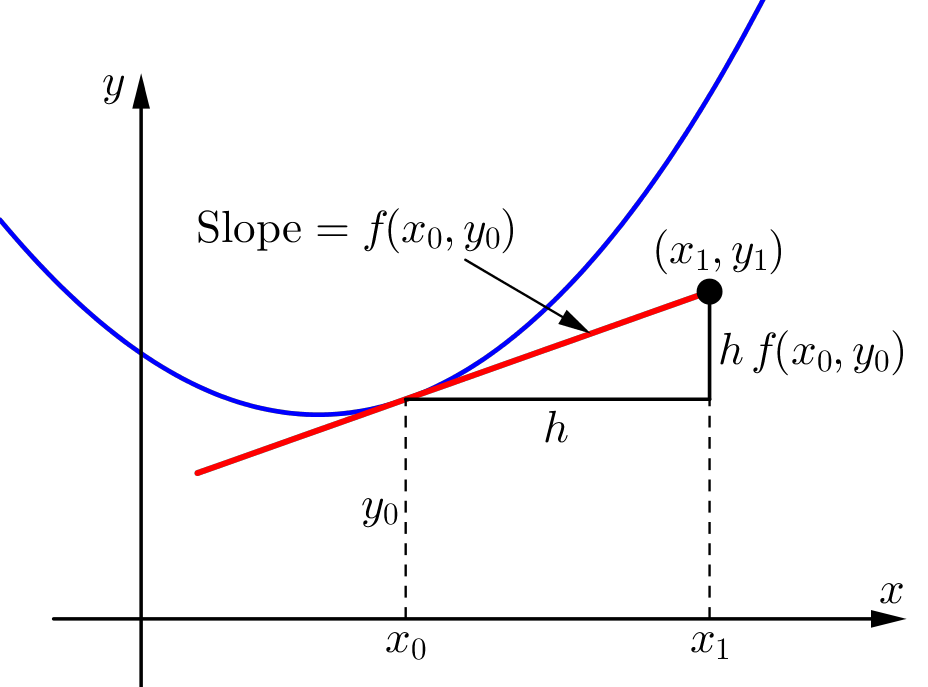

### Physics Pinpoint 🔎: Nuclear Fission

We now implement the method to compute the multiplication of nuclei in nuclear fission. In nuclear fission, a heavy nucleus splits into two lighter nuclei and releases energy and neutrons. The neutrons can then trigger more fissions, creating a chain reaction that grows exponentially.

Suppose we start with 1 kg of uranium-235 as our fissile material, which contains `NumAtoms` of nuclei:

Mass = 1;
MolarMass = 235;
AvogadroConst = 6.02e23;
NumAtoms = Mass / MolarMass * AvogadroConst

Through the splitting of nucleus, the nuclei multiply at the rate of $r=1\ldotp 01$ per second per individual nucleus. How many nuclei are there after 10 seconds? Assuming that the nuclei multiply continuously and without restriction, we can model this growth with the DE:


$$\textrm{dN}/\textrm{dt}=\textrm{rN},\;N\left(0\right)=N_0 =2\ldotp 5617\times {10}^{21}$$


where $N\left(t\right)$ is the population size at time $t$. This process is called exponential growth. The equation may be solved analytically to give the well-known formula for exponential growth:


$$N\left(t\right)=N_0 e^{\textrm{rt}}$$


To solve the same equation numerically, we apply Euler’s algorithm to it to get:


$$N_{i+1} =N_i +{\textrm{hrN}}_i$$


where the initial value $N_1 =2\ldotp 5617\times {10}^{21}$. It is trivial to program Euler’s method through the following script implements by taking $h=0\ldotp 5$. It also computes the exact solution for comparison:

StepLength =0.001; % h
GrowthRate = 1.01; % r
InitialTime = 0; % t0
FinalTime = 10; % tf
NumSteps = round((FinalTime - InitialTime) / StepLength); % n
NumNuclei = zeros(1, NumSteps + 1);
NumNuclei(1) = NumAtoms;
Time = InitialTime : StepLength : FinalTime;
for i = 1 : NumSteps
    NumNuclei(i + 1) = NumNuclei(i) + GrowthRate * StepLength * NumNuclei(i);
end

% Comparison with analytical solution
syms N(t) N0 r
DE = diff(N, t) == r*N
N(t) = dsolve(DE, N(0) == N0)
EqNumNuclei = subs(N, [r, N0], [GrowthRate, NumAtoms]);
plot(Time, NumNuclei, Time, EqNumNuclei(Time));
NumericalLegend = sprintf('Numerical (h = %.2f)', StepLength); 
legend(NumericalLegend, 'Analytical');
title('Nuclear fission (Euler''s method)');
xlabel('Time, t (second)'); ylabel('Number of nuclei, N');

The numerical solution will improve if we make $h$ smaller, but there will always be some value of $t$ where the error exceeds some acceptable limit. In some cases, Euler’s method performs better than it does here, but there are other numerical methods which always do better than Euler.

## Runge-Kutta Method

There are a variety of algorithms, under the general name of Runge-Kutta, which can be used to integrate systems of ODEs. MATLAB has plenty of ODE solvers, among them are `ode23` (second/third order) and `ode45` (fourth/fifth order), which implement Runge-Kutta methods. (The order of a numerical method is the power of $h$ (i.e., $\textrm{dt}$) in the leading error term. Since $h$ is generally very small, the higher the power, the smaller the error).

As an example, based on the Fourth Order Runge-Kutta Method (typically abbreviated as RK4), the estimation of the the next value of $y$ (i.e., $y_{i+1}$) using known initial values, i.e., $x_i$ and $y_i$ is given by:


$$y_{i+1} =y_i +{\textrm{hT}}_4 \left(x_i ,y_{i,} ,h\right)$$


where $T_4$ is given by:


$$T_4 =\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)$$


that consists of four subformulae as follows:


$$k_1 =f\left(x_i ,y_i \right)$$



$$k_2 =f\left(x_i +\frac{h}{2},y_i +\frac{h}{2}k_1 \right)$$



$$k_3 =f\left(x_i +\frac{h}{2},y_i +\frac{h}{2}k_2 \right)$$



$$k_4 =f\left(x_i +h,y_i +hk_3 \right)$$


### Single Differential Equations

Here’s how to use `ode23` to solve the bacteria growth problem. Start by writing an anonymous function for the right-hand side of the DE to be solved. The function must have input variables `Time` and `NumNuclei` in this case (i.e., independent and dependent variables of the DE):

GrowthRate = 1.01;
RHSFunc = @(Time, NumNuclei) GrowthRate * NumNuclei;
InitialTime = 0;
FinalTime = 10;
StepLength = 0.5;
InitialNumNuclei = NumAtoms;
TimeVector = InitialTime : StepLength : FinalTime;
[Time, NumNuclei] = ode23(RHSFunc, TimeVector, InitialNumNuclei);

% Comparison with analytical solution
plot(Time, NumNuclei, Time, EqNumNuclei(Time));
NumericalLegend = sprintf('Numerical (h = %.2f)', StepLength); 
legend(NumericalLegend, 'Analytical');
title('Nuclear fission (Runge-Kutta method)');
xlabel('Time, t (second)'); ylabel('Number of nuclei, N');

The output arguments are two vectors: the solutions `NumNuclei` at times `Time`. For $t=10$,` ode23` gives a value of  $6\ldotp 1834\times {10}^{25}$ nuclei, which has an error of only 0.84% compared to the exact solution (i.e., $6\ldotp 2360\times {10}^{25}$). 

If you need still more accurate numerical solutions, you can use `ode45` instead:

[~, NumNuclei] = ode45(RHSFunc, TimeVector, InitialNumNuclei);
NumNuclei(end)

 It gives a final value for the bacteria of $6\ldotp 2371\times {10}^{25}$—an error of about 0.019%.

### Systems of Differential Equations and Chaos

The reason that weather prediction is so difficult and forecasts are so erratic is no longer thought to be the complexity of the system but the nature of the DEs modeling it. These DEs belong to a class referred to as chaotic. Such equations will produce wildly different results when their initial conditions are changed infinitesimally. In other words, accurate weather prediction depends crucially on the accuracy of the measurements of the initial conditions. 

Edward Lorenz, a research meteorologist, discovered this phenomenon in 1961. Although his original equations are far too complex to consider here, the following much simpler system has the same essential chaotic features:


$$\textrm{dx}/\textrm{dt}=10\left(y-x\right)$$



$$\textrm{dy}/\textrm{dt}=-\textrm{xz}+28x-y$$



$$\textrm{dz}/\textrm{dt}=\textrm{xy}-8z/3$$


This system of DEs may be solved very easily with the MATLAB ODE solvers. The idea is to solve the DEs with certain initial conditions, plot the solution, then change the initial conditions very slightly, and superimpose the new solution over the old one to see how much it has changed.

A function `lorenz` is written to represent the right-hand sides of the system. We begin by solving the system with the initial conditions $x\left(0\right)=-2,y\left(0\right)=-3\ldotp 5$ and $z\left(0\right)=21$ from $t=0$ to $t=10$. Then, plot $y\left(t\right)$ only for an easier comparison:

InitialValues = [-2, -3.5, 21];
[Time, Var] = ode45(@lorenz, [0, 10], InitialValues);
plot(Time, Var(:, 2), DisplayName = 'ode45, x(0) = -2');
xlabel('Time, t'); ylabel('y');
title('ODE solvers (Runge-Kutta method)')
legend(AutoUpdate = 'on');

Let’s just change the initial value of $x\left(0\right)$, from $-2$ to $-2\ldotp 04$—that’s a change of only $2%$, and in only one of the three initial values:

InitialValues = [-2.04, -3.5, 21];
[Time, Var] = ode45(@lorenz, [0, 10], InitialValues);
hold on
plot(Time, Var(:, 2), DisplayName = 'ode45, x(0) = -2.04');

Now solve the system with the original initial values using `ode23` this time:

InitialValues = [-2, -3.5, 21];
[Time, Var] = ode23(@lorenz, [0, 10], InitialValues);
plot(Time, Var(:, 2), DisplayName = 'ode23, x(0) = -2');

A strange thing happens—the solutions begin to deviate wildly for $t>1\ldotp 5$. The initial conditions are the same—the only difference is the order of the Runge-Kutta method. 

Finally solve the system with `ode23s` and superimpose the solution. The `s` stands for ‘stiff’. For a stiff DE, solutions can change on a time scale that is very short compared to the interval of integration:

InitialValues = [-2, -3.5, 21];
[Time, Var] = ode23s(@lorenz, [0, 10], InitialValues);
plot(Time, Var(:, 2), DisplayName = 'ode23s, x(0) = -2');
hold off

The explanation is that `ode23`, `ode23s` and `ode45` all have numerical inaccuracies (if one could compare them with the exact solution—which incidentally can’t be found). However, the numerical inaccuracies are different in the three cases. This difference has the same effect as starting the numerical solution with very slightly different initial values.

How do we ever know when we have the ‘right’ numerical solution? Well, we don’t—the best we can do is increase the accuracy of the numerical method until no further wild changes occur over the interval of interest. So in our example we can only be pretty sure of the solution for $t<5$ (using `ode23s` or `ode45`). If that’s not good enough, you have to find a more accurate DE solver.

### Physics Pinpoint 🔎: Radioactive Decay

The basic equation for modeling radioactive decay is $\textrm{dx}/\textrm{dt}=-\textrm{rx}$, where $x$ is the amount of the radioactive substance at time $t$, and $r$ is the decay rate. Some radioactive substances decay into other radioactive substances, which in turn also decay. For example, Strontium 92 ($r_1 =0\ldotp 256$ per hr) decays into Yttrium 92 ($r_2 =0\ldotp 127$ per hr), which in turn decays into Zirconium. Write down a differential equation for each Strontium, Yttrium and Zirconium to describe what is happening. Starting at $t=0$ with $5\times {10}^{26}$ atoms of Strontium 92 and none of Yttrium and Zirconium, use the Runge-Kutta method (`ode23`) to solve the equations up to $t=8$ hours in steps of $1/3$ hr. Also use Euler’s method for the same problem, and compare your results.

% Runge-Kutta method
StepSize = 1/3;
TimeSpan = 0 : StepSize : 8;
InitialAmount = [5e26, 0, 0];
[Time, Amount] = ode23(@radioactiveODE, TimeSpan, InitialAmount);
[SrRK, YRK, ZrRK] = deal(Amount(:, 1), Amount(:, 2), Amount(:, 3));
plot(Time, SrRK, DisplayName = 'Stronitum');
hold on
plot(Time, YRK, DisplayName = 'Yttrium');
plot(Time, ZrRK, DisplayName = 'Zirconium');
hold off
legend
xlabel('Time, t (hour)'); ylabel('Number of atoms');
title('Radioactive substances versus time');
subtitle('Runge-Kutta method');

% Euler's method
NumSteps = numel(TimeSpan);
[SrEu, YEu, ZrEu] = deal(zeros(1, NumSteps));
SrEu(1)= InitialAmount(1);
for i = 1 : NumSteps - 1
    SrEu(i + 1) = SrEu(i) + StepSize*(-0.256 * SrEu(i));
    YEu(i + 1) = YEu(i) + StepSize*(0.256 * SrEu(i) - 0.127*YEu(i));
    ZrEu(i + 1) = ZrEu(i) + StepSize*(0.127 * YEu(i));
end
plot(Time, SrEu, DisplayName = 'Stronitum');
hold on
plot(Time, YEu, DisplayName = 'Yttrium');
plot(Time, ZrEu, DisplayName = 'Zirconium');
hold off
legend
xlabel('Time, t (hour)'); ylabel('Number of atoms');
title('Radioactive substances versus time');
subtitle('Euler''s method');

% Error in respect to the actual solution for Strontium
SrActualFinal = 6.450e25;
RKPercentError = 100 * abs(SrActualFinal - SrRK(end)) / SrActualFinal
EuPercentError = 100 * abs(SrActualFinal - SrEu(end)) / SrActualFinal

## Partial Differential Equation

The numerical solution of partial differential equations (PDEs) is a vast subject, but, a class of PDEs called parabolic often lead to solutions in terms of sparse matrices. One such example is heat conduction, which is delved next. 

### Physics Pinpoint 🔎: Heat Conduction

The conduction of heat along a thin uniform rod may be modeled by the partial differential equation:


$$\frac{\partial u}{\partial t}=\frac{\partial^2 u}{\partial x^2 }$$


where $u\left(x,t\right)$ is the temperature distribution a distance $x$ from one end of the rod at time $t$, and assuming that no heat is lost from the rod along its length.

We set up a rectangular grid, with step-lengths of $h$ and $k$ in the $x$ and $t$ directions respectively. A general point on the grid has coordinates $x_i =\textrm{ih}$, $y_j =\textrm{jk}$. A concise notation for $u\left(x,\;t\right)$ at $x_i$, $y_j$ is then simply $u_{i,j}$ . Truncated Taylor series may then be used to approximate the PDE by a finite difference scheme. The left-hand side of the following equation is usually approximated by a forward difference:


$$\frac{\partial u}{\partial t}=\frac{u_{i,j+1} -u_{i,j} }{k}$$


One way of approximating the right-hand side of the equation is by the scheme:


$$\frac{\partial^2 u}{\partial x^2 }=\frac{u_{i+1,j} -{2u}_{i,j} +u_{i-1,j} }{h^2 }$$


If however we replace the right-hand side of the scheme in the previous equation by the mean of the finite difference approximation on the $j$-th and $\left(j+1\right)$-th time rows, we get (after a certain amount of algebra) the following scheme for the initial partial DE:


$$-{\textrm{ru}}_{i-1,j+1} +\left(2+2r\right)u_{i,j+1} -{\textrm{ru}}_{i+1,j+1} ={\textrm{ru}}_{i-1,j} +\left(2-2r\right)u_{i,j} +{\textrm{ru}}_{i+1,j}$$


where $r=k/h^2$. This is known as the Crank-Nicolson implicit method, since it involves the solution of a system of simultaneous equations, as we shall see. To illustrate the method numerically, let’s suppose that the rod has a length of 1 unit, and that its ends are in contact with blocks of ice, i.e., the boundary conditions are:


$$u\left(0,\;t\right)=u\left(1,\;t\right)=0$$


Suppose also that the initial temperature (initial condition) is:


$$u\left(x,0\right)=\left\lbrace \begin{array}{ll}
2x, & 0\le x\le 1/2\\
2\left(1-x\right), & 1/2<x\le 1
\end{array}\right.$$


This situation could come about by heating the center of the rod for a long time, with the ends kept in contact with the ice, removing the heat source at time $t=0$. This particular problem has symmetry about the line $x=1/2$; we exploit this now in finding the solution. If we take $h=0\ldotp 1$ and $k=0\ldotp 01$, we will have $r=1$, and the previous equation becomes:


$$-u_{i-1,j+1} +4u_{i,j+1} -u_{i+1,j+1} =u_{i-1,j} +u_{i+1,j}$$


Putting $j=0$ in the equation generates the following set of equations for unknowns $u_{i,1}$ (i.e., after one time step $k$) up to the midpoint of the rod, which is represented by $i=5$, i.e., $x=\textrm{ih}=0\ldotp 5$. The subscript $j=1$ has been dropped for clarity:


$$\begin{array}{l}
\;\;\;\;\;0+4u_1 -u_2 =0+0\ldotp 4\\
-u_1 +4u_2 -u_3 =0\ldotp 2+0\ldotp 6\\
-u_2 +4u_3 -u_4 =0\ldotp 4+0\ldotp 8\\
-u_3 +4u_4 -u_5 =0\ldotp 6+1\ldotp 0\\
-u_4 +4u_5 -u_6 =0\ldotp 8+0\ldotp 8
\end{array}$$


Symmetry then allows us to replace $u_6$ in the last equation by $u_4$. These equations can be written in matrix form as:


$$\left\lbrack \begin{array}{ccccc}
4 & -1 & 0 & 0 & 0\\
-1 & 4 & -1 & 0 & 0\\
0 & -1 & 4 & -1 & 0\\
0 & 0 & -1 & 4 & -1\\
0 & 0 & 0 & -2 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
u_3 \\
u_4 \\
u_5 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 4\\
0\ldotp 8\\
1\ldotp 2\\
1\ldotp 6\\
1\ldotp 6
\end{array}\right\rbrack$$


The matrix ($\mathbf{A}$) on the left is known as a tridiagonal matrix. Having solved for the $u_{i,1}$ we can then put $j=1$ and proceed to solve for the $u_{i,2}$, and so on. The matrix system can of course be solved directly in MATLAB with the left division operator. In the script below, the general form of the equation is taken as $\textrm{Av}=\mathbf{g}$. Care needs to be taken when constructing the matrix $\mathbf{A}$. The following notation is often used:


$$\mathbf{A}=\left\lbrack \begin{array}{cccccc}
b_1  & c_1  &  &  &  & \\
a_2  & b_2  & c_2  &  &  & \\
 & a_3  & b_3  & c_3  &  & \\
 &  &  & \ldotp \ldotp \ldotp  &  & \\
 &  &  & a_{n-1}  & b_{n-1}  & c_{n-1} \\
 &  &  &  & a_n  & b_n 
\end{array}\right\rbrack$$


$\mathbf{A}$ is an example of a sparse matrix. The script below implements the general Crank-Nicolson scheme of the equation to solve this particular problem over 10 time steps of $k=0\ldotp 01$. The step-length is specified by $h=1/2n$ because of symmetry. $r$ is therefore not restricted to the value 1, although it takes this value here. The script exploits the sparsity of $\mathbf{A}$ by using the `sparse` function:

n = 5;
k = 0.01;
h = 1 / (2 * n); 
r = k / h ^ 2;
b = sparse(1:n, 1:n, 2+2*r, n, n);
c = sparse(1:n-1, 2:n, -r, n, n); 
a = sparse(2:n, 1:n-1, -r, n, n);
A = a + b + c;
A(n, n - 1) = -2 * r;
full(A)
disp(' ')
u0 = 0; 
u = 2* h *(1 : n)
u(n + 1) = u(n - 1);
disp([0 u(1 : n)])
for t = k*(1 : 10)
    g = r * ([u0 u(1 : n - 1)] + u(2 : n + 1)) + (2 - 2 * r) * u(1 : n);
    v = A\g';
    disp([t v'])
    u(1 : n) = v;
    u(n + 1) = u(n - 1);
end

**Local Functions**

function Func = lorenz(~, Var)
Func = zeros(3, 1);
Func(1) = 10 * (Var(2) - Var(1));
Func(2) = -Var(1) * Var(3) + 28 * Var(1) - Var(2);
Func(3) = Var(1) * Var(2) - 8 * Var(3) / 3;
end

function dNdt = radioactiveODE(~, N)
% N(1): Strontium
% N(2): Yttrium
% N(3): Zirconium
dNdt = NaN(3, 1);
dNdt(1) = -0.256 * N(1);
dNdt(2) = 0.256 * N(1) - 0.127*N(2);
dNdt(3) = 0.127 * N(2);
end